## Spatial Analysis

L = 0.01;
N_L = 100;
mu_0 = pi*4e-7;
eps_0 = 8.85418782e-12;
omega = 2*pi*(10^(10));
Z_L = 1e2;
vp = 0.5e8;
z = linspace(0, L, N_L)

z =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


**Derived Solution**

E = omega/vp;


$$\Gamma(z)=\frac12 e^{-\omega/v_p z}$$


Gamma = 0.5*exp(-E.*z);
dGamma = 0.5*(-E)*exp(-E.*z);

Plotting Gamma

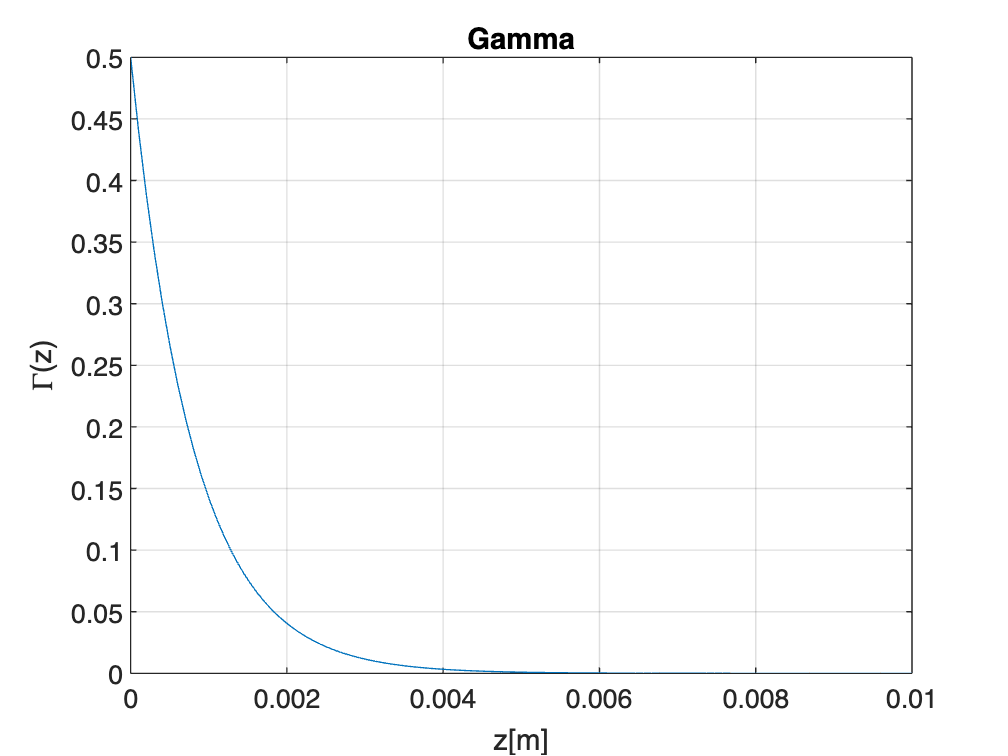

plot(z, Gamma)
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("Gamma")


$$\epsilon(z)=\left(\frac1{\displaystyle I(L)\frac{Z_L}{\sqrt\mu_0}I^{-1}(z)+I^{-1}(z)\int_L^zI(x)b(x)dx}\right)^2$$


a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));
a

a = 1.0e+03 *

    1.6755    1.3732    1.1476    0.9722    0.8316    0.7165    0.6206    0.5396    0.4706    0.4114    0.3603    0.3159    0.2773    0.2436    0.2141    0.1882    0.1656    0.1457    0.1283    0.1129    0.0994    0.0875    0.0771    0.0679    0.0598    0.0526    0.0464    0.0408    0.0360    0.0317    0.0279    0.0246    0.0216    0.0191    0.0168    0.0148    0.0130    0.0115    0.0101    0.0089    0.0078    0.0069    0.0061    0.0054    0.0047    0.0042    0.0037    0.0032    0.0028    0.0025


b

b = 1.0e+08 *

   0.0000 + 1.8783i   0.0000 + 1.5393i   0.0000 + 1.2864i   0.0000 + 1.0898i   0.0000 + 0.9323i   0.0000 + 0.8032i   0.0000 + 0.6957i   0.0000 + 0.6049i   0.0000 + 0.5276i   0.0000 + 0.4612i   0.0000 + 0.4038i   0.0000 + 0.3541i   0.0000 + 0.3108i   0.0000 + 0.2730i   0.0000 + 0.2400i   0.0000 + 0.2110i   0.0000 + 0.1856i   0.0000 + 0.1634i   0.0000 + 0.1438i   0.0000 + 0.1266i   0.0000 + 0.1114i   0.0000 + 0.0981i   0.0000 + 0.0864i   0.0000 + 0.0761i   0.0000 + 0.0670i   0.0000 + 0.0590i   0.0000 + 0.0520i   0.0000 + 0.0458i   0.0000 + 0.0403i   0.0000 + 0.0355i   0.0000 + 0.0313i   0.0000 + 0.0275i   0.0000 + 0.0243i   0.0000 + 0.0214i   0.0000 + 0.0188i   0.0000 + 0.0166i   0.0000 + 0.0146i   0.0000 + 0.0129i   0.0000 + 0.0113i   0.0000 + 0.0100i   0.0000 + 0.0088i   0.0000 + 0.0077i   0.0000 + 0.0068i   0.0000 + 0.0060i   0.0000 + 0.0053i   0.0000 + 0.0047i   0.0000 + 0.0041i   0.0000 + 0.0036i   0.0000 + 0.0032i   0.0000 + 0.0028i


Integrating Factor $I(z)=e^{\int_L^z-a(x)dx}$

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(L/N_L) - trapz(a)*(L/N_L);

% Calculate I(z)
I = exp(-int_a);
I

I =     2.9760    2.5552    2.2526    2.0261    1.8514    1.7135    1.6027    1.5123    1.4378    1.3758    1.3237    1.2797    1.2423    1.2104    1.1830    1.1595    1.1391    1.1215    1.1063    1.0930    1.0815    1.0714    1.0626    1.0550    1.0483    1.0424    1.0372    1.0327    1.0288    1.0253    1.0222    1.0196    1.0172    1.0151    1.0133    1.0117    1.0103    1.0091    1.0080    1.0070    1.0062    1.0055    1.0048    1.0042    1.0037    1.0033    1.0029    1.0025    1.0022    1.0020


D = cumtrapz(I.*b)*(L/N_L) - trapz(I.*b)*(L/N_L);

Plotting $\epsilon(z)$

eps = ( I(N_L)*(Z_L/sqrt(mu_0))*I.^(-1) + I.^(-1).*D ).^(-2)

eps = 1.0e-09 *

  -0.1114 + 0.1064i  -0.0994 + 0.1370i  -0.0780 + 0.1651i  -0.0485 + 0.1870i  -0.0139 + 0.2000i   0.0219 + 0.2031i   0.0553 + 0.1973i   0.0839 + 0.1849i   0.1066 + 0.1685i   0.1234 + 0.1502i   0.1352 + 0.1319i   0.1428 + 0.1146i   0.1473 + 0.0990i   0.1496 + 0.0851i   0.1502 + 0.0730i   0.1499 + 0.0626i   0.1488 + 0.0537i   0.1474 + 0.0461i   0.1458 + 0.0397i   0.1441 + 0.0342i   0.1424 + 0.0295i   0.1408 + 0.0255i   0.1393 + 0.0221i   0.1379 + 0.0191i   0.1366 + 0.0166i   0.1354 + 0.0145i   0.1343 + 0.0126i   0.1333 + 0.0110i   0.1325 + 0.0096i   0.1317 + 0.0084i   0.1310 + 0.0073i   0.1304 + 0.0064i   0.1298 + 0.0056i   0.1294 + 0.0049i   0.1289 + 0.0043i   0.1285 + 0.0038i   0.1282 + 0.0033i   0.1279 + 0.0029i   0.1276 + 0.0026i   0.1274 + 0.0023i   0.1272 + 0.0020i   0.1270 + 0.0017i   0.1269 + 0.0015i   0.1267 + 0.0013i   0.1266 + 0.0012i   0.1265 + 0.0010i   0.1264 + 0.0009i   0.1263 + 0.0008i   0.1262 + 0.0007i   0.1262 + 0.0006i


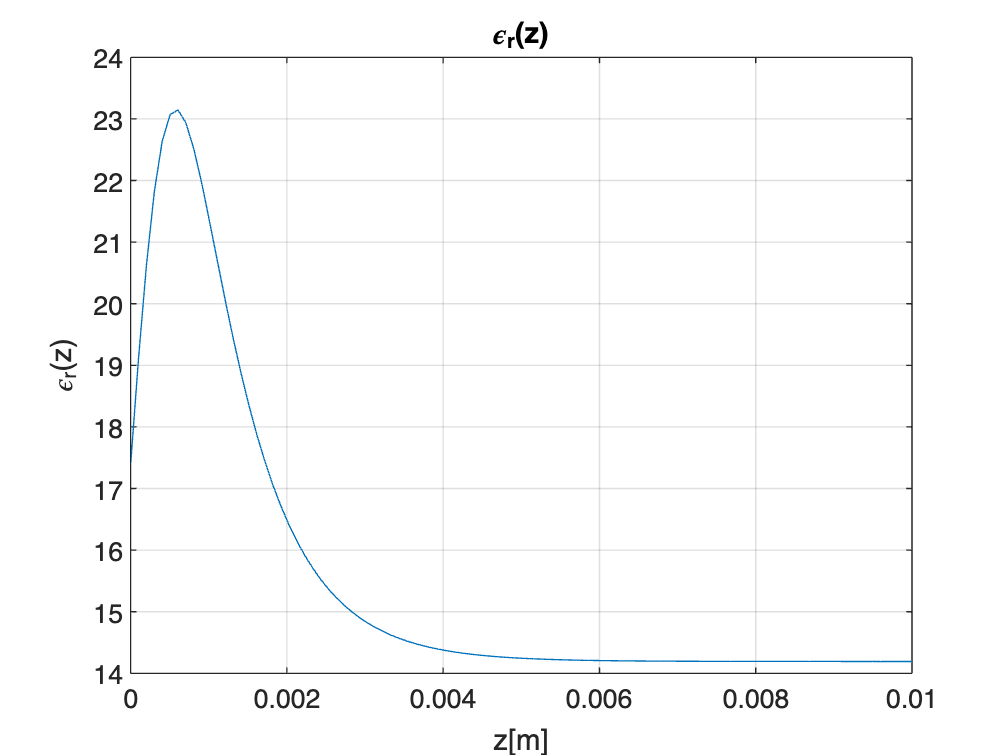

plot(z, abs(eps/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("\epsilon_r(z)")

## ode45

clear z;
Gamma = @(z)0.5*exp(-E.*z);
dGamma = @(z)0.5*(-E)*exp(-E.*z);
a = @(z) -2*dGamma(L-z).*(1./(1-Gamma(L-z).^2));
b = @(z) 4*1j*omega*sqrt(mu_0).*(Gamma(L-z)./(1-Gamma(L-z).^2));

ODE is $\xi'(z)+a(z)\xi(z)+b(z)\xi^2(z)=0$

`Let `$z_r=L-z$`. Then we have`


$$\xi'(L-z_r)+a(L-z_r)\xi(L-z_r)+b(L-z_r)\xi^2(L-z_r)=0$$


`Define `$\xi(L-z_r)=\xi_r(z_r)$`, `$a(L-z_r)=a_r(z_r)$`, and `$b(L-z_r)=b_r(z_r)$

`We solve for `$\xi_r(z_r)$` and by substition we have`


$$-\xi_r'(z_r)+a_r(z_r)\xi_r(z_r)+b_r(z_r)\xi_r(z_r)^2=0$$


odefun = @(z, v) -a(z)*v - b(z);
[z, v] = ode45(odefun, [0, L], (Z_L/sqrt(mu_0))^(1));
eps_ode = flip((1./v).^2)

eps_ode = 1.0e-09 *

  -0.1124 + 0.1059i
  -0.0664 + 0.1759i
   0.0187 + 0.2035i
   0.0932 + 0.1792i
   0.1336 + 0.1349i
   0.1483 + 0.0945i
   0.1500 + 0.0647i
   0.1470 + 0.0443i
   0.1429 + 0.0307i
   0.1390 + 0.0214i


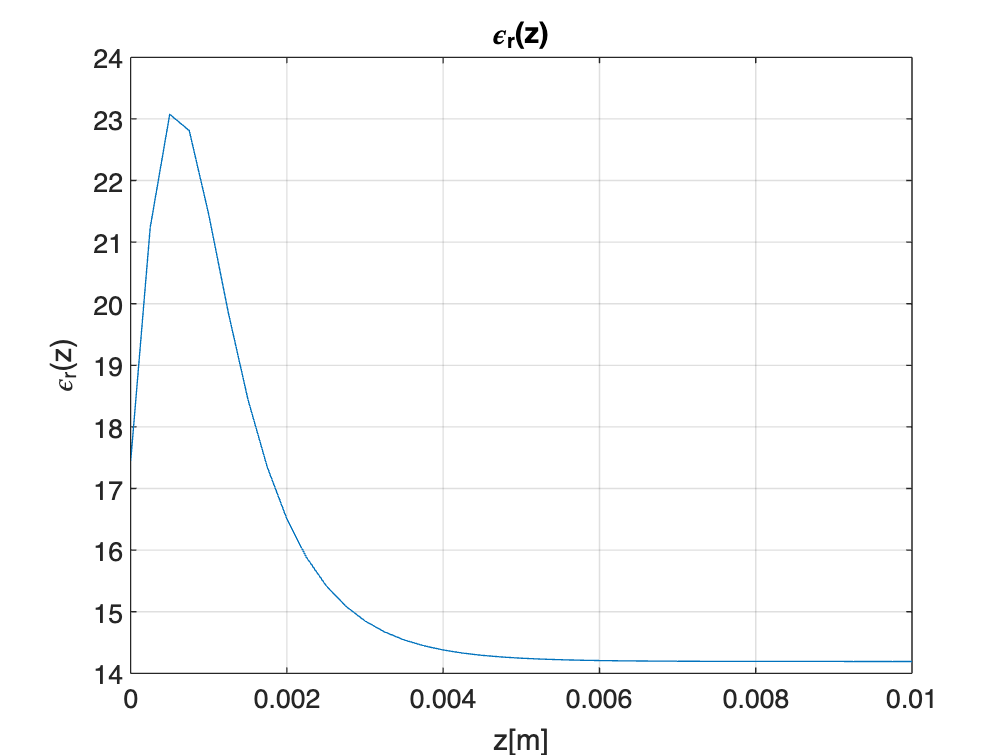


plot(z, abs(eps_ode/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("\epsilon_r(z)")

## Temporal Analysis

clear Gamma dGamma
T = 1e-10;
N_T = 100;
t = linspace(0, T, N_T)

t = 1.0e-10 *

         0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


**Derived Solution**

F = omega;


$$\Gamma(t)=\frac12-\frac12 te^{-\omega t}$$


Gamma = 0.5-0.5*t.*exp(-F.*t);
dGamma = -0.5*exp(-F.*t) - 0.5*(-F)*exp(-F.*t);

Plot of Gamma

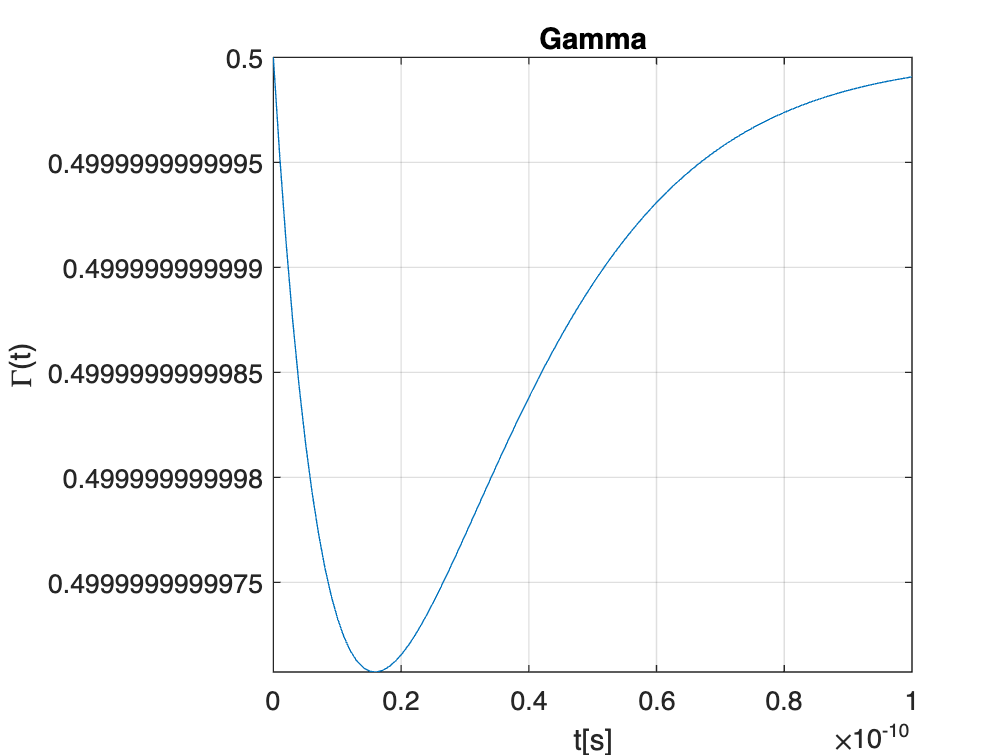

plot(t, Gamma)
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("Gamma")


$$\epsilon(t)=\left(\frac1{\displaystyle I(0)\frac1{\xi(0)}I^{-1}(t)+I^{-1}(t)\int_0^t-I(\tau)b(\tau)d\tau}\right)^2$$


a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));
a

a = 1.0e+10 *

   -8.3776   -7.8624   -7.3789   -6.9251   -6.4993   -6.0996   -5.7245   -5.3725   -5.0421   -4.7321   -4.4411   -4.1680   -3.9117   -3.6711   -3.4454   -3.2335   -3.0346   -2.8480   -2.6729   -2.5085   -2.3543   -2.2095   -2.0736   -1.9461   -1.8264   -1.7141   -1.6087   -1.5098   -1.4169   -1.3298   -1.2480   -1.1713   -1.0993   -1.0317   -0.9682   -0.9087   -0.8528   -0.8004   -0.7511   -0.7049   -0.6616   -0.6209   -0.5827   -0.5469   -0.5133   -0.4817   -0.4521   -0.4243   -0.3982   -0.3737


b

b = 1.0e+08 *

   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i   0.0000 + 1.8783i



% Numerically integrate a from L to z
int_a = cumtrapz(a)*(T/N_T) - cumtrapz(a(1))*(T/N_T);

% Calculate I(z)
I = exp(int_a);
I

I =     1.0000    0.9220    0.8544    0.7954    0.7438    0.6983    0.6583    0.6227    0.5911    0.5629    0.5377    0.5150    0.4947    0.4762    0.4596    0.4445    0.4308    0.4183    0.4069    0.3965    0.3870    0.3783    0.3702    0.3629    0.3561    0.3498    0.3441    0.3388    0.3338    0.3293    0.3251    0.3212    0.3175    0.3142    0.3110    0.3081    0.3054    0.3029    0.3006    0.2984    0.2964    0.2945    0.2927    0.2911    0.2895    0.2881    0.2867    0.2855    0.2843    0.2832


D = cumtrapz(I.*b)*(T/N_T) - cumtrapz(I(1)*b(1))*(T/N_T);
eps = ( I(1)*(1/(5*sqrt(eps_0)))*I.^(-1) + I.^(-1).*D ).^(-2)

eps = 1.0e-09 *

   0.2214 + 0.0000i   0.1882 - 0.0000i   0.1616 - 0.0000i   0.1400 - 0.0000i   0.1224 - 0.0000i   0.1080 - 0.0000i   0.0959 - 0.0000i   0.0858 - 0.0000i   0.0773 - 0.0000i   0.0701 - 0.0000i   0.0640 - 0.0000i   0.0587 - 0.0000i   0.0542 - 0.0000i   0.0502 - 0.0000i   0.0468 - 0.0000i   0.0437 - 0.0000i   0.0411 - 0.0000i   0.0387 - 0.0000i   0.0367 - 0.0000i   0.0348 - 0.0000i   0.0331 - 0.0000i   0.0317 - 0.0000i   0.0303 - 0.0000i   0.0291 - 0.0000i   0.0281 - 0.0000i   0.0271 - 0.0000i   0.0262 - 0.0000i   0.0254 - 0.0000i   0.0247 - 0.0000i   0.0240 - 0.0000i   0.0234 - 0.0000i   0.0228 - 0.0000i   0.0223 - 0.0000i   0.0218 - 0.0000i   0.0214 - 0.0000i   0.0210 - 0.0000i   0.0206 - 0.0000i   0.0203 - 0.0000i   0.0200 - 0.0000i   0.0197 - 0.0000i   0.0194 - 0.0000i   0.0192 - 0.0000i   0.0190 - 0.0000i   0.0188 - 0.0000i   0.0186 - 0.0000i   0.0184 - 0.0000i   0.0182 - 0.0000i   0.0180 - 0.0000i   0.0179 - 0.0000i   0.0178 - 0.0000i


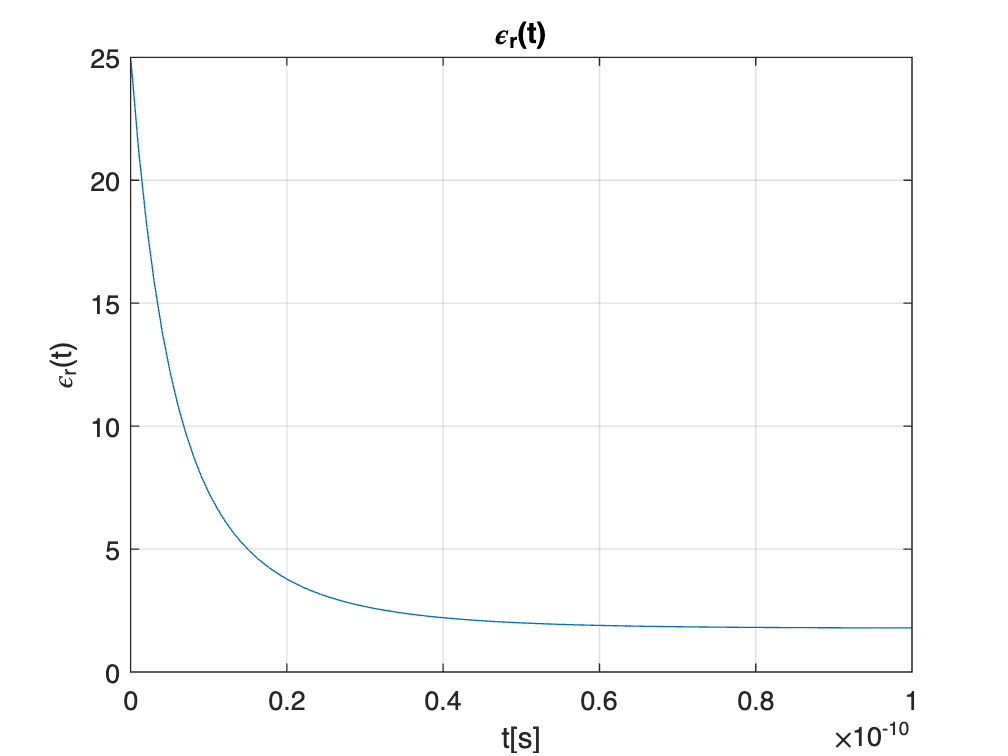

plot(t, abs(eps/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("\epsilon_r(t)")

### ode45

clear t;
Gamma = @(t) 0.5-0.5*exp(-F*t);
dGamma = @(t) -0.5*(-F)*exp(-F*t);
a = @(t) -2.*dGamma(t).*(1./(1-Gamma(t).^2));
b = @(t) 4*1j*omega*sqrt(mu_0).*(Gamma(t)./(1-Gamma(t).^2));

ODE is

odefun = @(t, v) -a(t)*v - b(t);
[t, v] = ode45(odefun, [0, 1e-10], (5*sqrt(eps_0))^(-1));
eps_ode = (1./v).^2

eps_ode = 1.0e-09 *

   0.2214 + 0.0000i
   0.2007 + 0.0000i
   0.1828 + 0.0000i
   0.1673 + 0.0000i
   0.1536 + 0.0000i
   0.1207 + 0.0000i
   0.0979 + 0.0000i
   0.0815 + 0.0000i
   0.0695 + 0.0000i
   0.0605 + 0.0000i


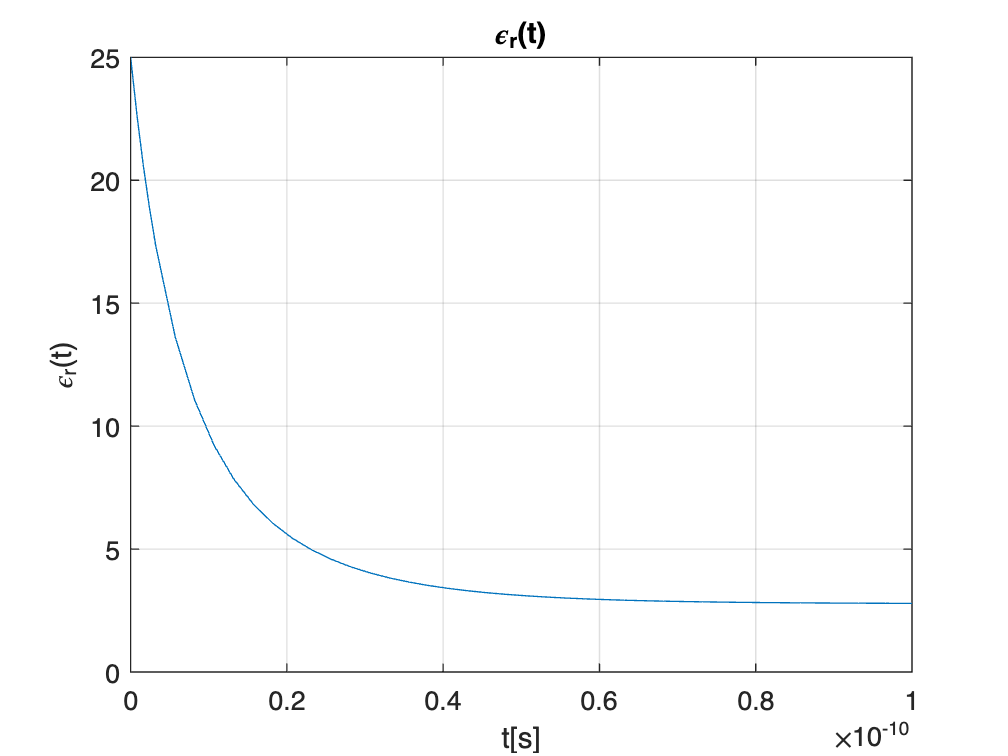


plot(t, abs(eps_ode/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("\epsilon_r(t)")